clear;

X_train = readtable('C:\Users\rgs88\OneDrive\Documents\Semester 1 Data Science MSc Projects\Machine Learning\ML_Retake\X_train.csv');
y_train = readtable('C:\Users\rgs88\OneDrive\Documents\Semester 1 Data Science MSc Projects\Machine Learning\ML_Retake\y_train.csv');
X_test = readtable('C:\Users\rgs88\OneDrive\Documents\Semester 1 Data Science MSc Projects\Machine Learning\ML_Retake\X_test.csv');
y_test = readtable('C:\Users\rgs88\OneDrive\Documents\Semester 1 Data Science MSc Projects\Machine Learning\ML_Retake\y_test.csv');

X_train = table2array(X_train);
y_train = table2array(y_train);
X_test = table2array(X_test);
y_test = table2array(y_test);

num_samples_train = 5000; % Number of training samples
num_samples_test = 1000;  % Number of test samples

random_indices_train = randperm(size(X_train, 1), num_samples_train);
X_train_subset = X_train(random_indices_train, :);

y_train_subset = y_train(random_indices_train, :);

random_indices_test = randperm(size(X_test,1), num_samples_test);
X_test_subset = X_test(random_indices_test, :);

y_test_subset = y_test(random_indices_test, :);


knn_mdl = fitcknn(X_train_subset, y_train_subset, 'NumNeighbors', 3);

y_pred_labels = predict(knn_mdl, X_test_subset);

% Evaluate the model
accuracy = sum(y_pred_labels == y_test_subset) / numel(y_test_subset);

% Display accuracy
disp(['Test Accuracy: ', num2str(accuracy * 100), '%']);

Test Accuracy: 93.1%


% Create a confusion matrix
C = confusionmat(y_test_subset, y_pred_labels);

% Display the confusion matrix
disp('Confusion Matrix:');

Confusion Matrix:


disp(C);

   105     0     0     0     0     0     1     0     0     0
     0   114     0     0     0     0     0     0     0     0
     1     4   100     0     0     0     0     2     1     0
     0     1     0    95     0     2     0     2     2     1
     0     2     0     0    79     0     4     1     0     3
     1     1     0     4     0    78     0     1     0     0
     3     0     0     0     0     0    89     0     0     0
     1     4     0     0     1     0     0    98     0     2
     2     1     0     5     3     2     0     2    87     2
     2     1     0     1     1     0     0     2     0    86



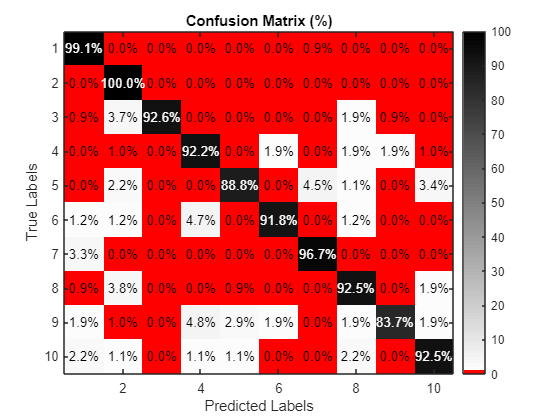



% Convert the confusion matrix to a percentage format
C_percent = 100 * C ./ sum(C, 2);

% Define custom colormap with red background and white text
redBackground = [1, 0, 0];
blackText = [0, 0, 0];
whiteText = [1, 1, 1];

% Create a custom colormap with red background and shades of white for text
customColormap = [redBackground; interp1([0, 100], [whiteText; blackText], 1:100)];

% Visualize the confusion matrix as a heatmap using imagesc
figure;
h = imagesc(C_percent);
colorbar;
colormap(customColormap);
clim([0, 100]); % Set the color axis range to match the percentages
title('Confusion Matrix (%)');
xlabel('Predicted Labels');
ylabel('True Labels');

% Display the percentage values on the heatmap in white or black based on intensity
textColors = repmat(C_percent(:) > 50, 1, 3); % Define text colors based on background intensity
textStrings = strtrim(cellstr(num2str(C_percent(:), '%.1f%%'))); % Convert values to string
[x, y] = meshgrid(1:size(C_percent, 2), 1:size(C_percent, 1)); % Create coordinate grid
text(x(:), y(:), textStrings(:), 'HorizontalAlignment', 'center', 'Color', 'k');

% Display the diagonal values in white text on the heatmap
for i = 1:size(C_percent, 1)
    text(i, i, num2str(C_percent(i, i), '%.1f%%'), 'HorizontalAlignment', 'center', 'Color', 'w');
end

% Create a confusion matrix
C = confusionmat(y_test_subset, y_pred_labels);

% Display the confusion matrix
disp('Confusion Matrix:');

Confusion Matrix:


disp(C);

     0     0     0     0     0     0     0     0   107     0
     0     0     0     0     0     0     0     0   121     0
     0     0     0     0     0     0     0     0    96     0
     0     0     0     0     0     0     0     0   108     0
     0     0     0     0     0     0     0     0    88     0
     0     0     0     0     0     0     0     0    83     0
     0     0     0     0     0     0     0     0    94     0
     0     0     0     0     0     0     0     0   108     0
     0     0     0     0     0     0     0     0   100     0
     0     0     0     0     0     0     0     0    95     0



% Calculate the observed agreement
po = sum(diag(C)) / sum(C(:));

% Calculate the chance agreement
pe = sum(sum(C, 1) .* sum(C, 2)) / sum(C(:))^2;

% Calculate Cohen's Kappa
kappa = (po - pe) / (1 - pe);

disp(['Cohen''s Kappa: ' num2str(kappa)]);

Cohen's Kappa: 0.9178


% Load the data and preprocess as you did before

% Define the range of hyperparameters to search
numNeighbors = [1, 3, 5, 7, 9]; % Example values for the number of neighbors

% Initialize variables to store best results
bestAccuracy = 0;
bestNumNeighbors = 0;
bestModel = [];

% Initialize array to store accuracies
allAccuracies = zeros(1, length(numNeighbors));

% Perform Grid Search
for i = 1:length(numNeighbors)
    k = numNeighbors(i);
    knn_mdl = fitcknn(X_train_subset, y_train_subset, 'NumNeighbors', k);
    y_pred_labels = predict(knn_mdl, X_test_subset);
    accuracy = sum(y_pred_labels == y_test_subset) / length(y_test_subset);
    
    disp(['NumNeighbors: ' num2str(k) ', Accuracy: ' num2str(accuracy)]);
    
    % Update best model if accuracy is better
    if accuracy > bestAccuracy
        bestAccuracy = accuracy;
        bestNumNeighbors = k;
        bestModel = knn_mdl;
    end
    
    % Store accuracy in the array
    allAccuracies(i) = accuracy;
end

NumNeighbors: 1, Accuracy: 0.931
NumNeighbors: 3, Accuracy: 0.926
NumNeighbors: 5, Accuracy: 0.928
NumNeighbors: 7, Accuracy: 0.924
NumNeighbors: 9, Accuracy: 0.925



% Display all accuracies
disp('All Accuracies:');

All Accuracies:


disp(allAccuracies);

    0.9310    0.9260    0.9280    0.9240    0.9250




disp(['Best NumNeighbors: ' num2str(bestNumNeighbors)]);

Best NumNeighbors: 1


disp(['Best Accuracy: ' num2str(bestAccuracy)]);

Best Accuracy: 0.931


% Create a confusion matrix
C = confusionmat(y_test_subset, y_pred);

% Display the confusion matrix
disp('Confusion Matrix:');

Confusion Matrix:


disp(C);

    98     0     1     2     0     4     0     0     2     0
     0   114     0     0     0     0     1     0     6     0
     3     0    80     5     3     0     1     2     2     0
     2     1     5    89     0     5     0     1     5     0
     0     1     0     1    74     1     3     1     1     6
     1     0     0     7     2    57     3     1    11     1
     1     0     0     0     1     2    88     0     2     0
     0     0     1     1     3     1     0    88     1    13
     3     2     5     1     2     5     3     1    76     2
     3     0     1     2     4     1     1     3     2    78



final_model_knn = fitcknn(X_train_subset, y_train_subset, 'NumNeighbors', 1);

Cohen's Kappa: 0.82447
